# Accelerating FBA on Large Whole-Body and Microbiome-Personalised Models with Gurobi

## Author(s):

Farid Zare ${}^{1,2,3}$

${}^1$ School of Medicine, University of Galway, University Rd, Galway, Ireland.

${}^2$ Institute for Clinical Trials, University of Galway, Galway, Ireland.

${}^3$ Digital Metabolic Twin Centre, University of Galway, Galway, Ireland.

## Reviewer(s):

## TL;DR

**Expected total runtime: ~6-10 min** (almost all of it is Section 4).

- **Warm-starting a related re-solve is the single biggest, and most reliable, win in this tutorial.** Solve once, perturb one diet-exchange bound (a routine "try a different diet" scenario), and re-solving from the first solve's basis was 28-32x faster than solving cold - consistently, on every model.

- `Crossover = 0` made a single FBA solve faster than the default algorithm on three of the four large models tested here - but was actually the **slowest** option on the fourth. Unlike warm-starting, do not assume it is a safe default; check it on your own model.

- Every configuration solved reliably on the raw Harvey/Harvetta files too, using their flux bounds exactly as distributed and no local file paths - all four models load with a single, portable `getDistributedModel` call each (Section 1).

- None of this helps `fluxVariability()` - its speed comes from heuristics that only work with a simplex solution, so forcing no-crossover there made FVA slower in every test.

## HOW TO USE THESE OPTIONS IN THE COBRA TOOLBOX

`Crossover` and warm-starting are two independent levers, useful in two different situations - a single big solve versus a **sequence** of related solves - so keep them separate rather than reaching for both at once.

**Crossover, for a single solve** (`optimizeCbModel`, once Gurobi is active via `changeCobraSolver('gurobi', 'all')`):

This is a Gurobi solver parameter, passed as a struct to any COBRA solver call - the same struct works with `solveCobraLP`/|solveCobraQP| directly:

**Warm-starting, for a sequence of related solves** - solve once, then feed that solution's basis into the **next**, related optimisation instead of starting it cold:

This is not a Gurobi parameter at all - `.basis` is a field on the **model** struct, forwarded straight to the solver. It only helps if `solution1` actually has a basis to give (see Section 2: that means `Crossover = 1`, not `0`), and it is only meaningful when `model2` is genuinely related to `model` - re-optimising the same network after changing a bound or two, not an unrelated problem.

**FVA** (`fluxVariability`) has its own dedicated no-crossover shortcut - see INTRODUCTION for why this tutorial does not recommend actually using it:

**Rule of thumb:** one solve, objective value only -> try `Crossover = 0`, but verify it actually helps on your model (Section 3 found it did not, on one of our four). Many related solves in sequence -> warm-start from the previous basis instead; do not force `Crossover = 0` there; see Section 5.

## INTRODUCTION

Flux balance analysis (FBA) solves a single linear program (LP):


$$\begin{array}{ll}\max/\min & c^{T}v\\\text{s.t.} & Sv=b\\ & l\leq v\leq u\end{array}$$


For a small model this takes a fraction of a second regardless of how the LP is solved. For **whole-body metabolic models** (WBMs) such as Harvey (male) and Harvetta (female) [1] - and especially for **microbiome-personalised** WBMs (mWBMs), which couple a WBM to an individual's reconstructed gut microbial community [2] - a single FBA problem can have hundreds of thousands of reactions and constraints. At that scale, **how** the LP is solved starts to matter as much as the model itself.

Gurobi offers two fundamentally different families of algorithm for continuous LPs, controlled by the `Method` parameter [3]:

- **Simplex** (primal, dual or automatic) walks along the edges of the feasible polytope from vertex to vertex, terminating at a vertex (basic feasible) solution. It can also be efficiently **warm-started** from a previously known solution basis - the second lever this tutorial covers.

- **Barrier** (interior-point) approaches the optimum from inside the polytope. Its iteration count grows very slowly with problem size, which is exactly what makes it attractive for very large LPs like the ones in this tutorial - but the solution it returns sits in the interior of the optimal face, not at a vertex, and it cannot be warm-started the same way.

Because many downstream routines expect a vertex solution, Gurobi by default runs an extra **crossover** phase after barrier finishes: a simplex clean-up that pivots the interior-point solution onto a vertex. Crossover can be a substantial fraction of total solve time on large, degenerate models - this tutorial measures exactly how substantial on real WBM-scale models, up to a quarter of a million reactions. Setting `Crossover = 0` skips this phase: the solve finishes as soon as barrier reaches its tolerance, trading solution precision - and that reusable basis - for speed.

That trade-off is the link between the two levers in this tutorial: skipping crossover is attractive for a single, one-off solve, but it throws away exactly the thing (a vertex basis) that makes warm-starting a **second**, related solve so effective. They solve different problems and should not be combined by default - see Section 5.

**CRITICAL STEP** This tutorial is about the barrier-without-crossover option (Gurobi `Method = 2`, `Crossover = 0`), used here via `optimizeCbModel()`'s solver-parameter struct. The same idea is also exposed for **flux variability analysis** (FVA) as the `'fastBarrier'` name-value pair of `fluxVariability()`. We benchmarked it there too while developing this tutorial and found the opposite result: `fluxVariability`'s own heuristics for short-circuiting reactions only pay off downstream of a simplex (vertex) solution, so forcing barrier-without-crossover made FVA **slower**, not faster, on every model and reaction subset we tried. This tutorial therefore focuses on FBA - a single solve, where there is no such heuristic to lose and the benefit is real and consistent, as shown below, even if its exact size varies from model to model. Despite the similarly-sounding name, none of this is the compiled `fastFVA()` function either, which only supports the IBM CPLEX solver and has nothing to do with Gurobi's crossover option.

All of the options discussed here are **Gurobi-specific**. They are only used when Gurobi is the active COBRA Toolbox solver; other solvers expose analogous (but differently named) parameters that are outside the scope of this tutorial.

## MATERIALS - EQUIPMENT SETUP

*Expected runtime: ~20 s.*

Please ensure that all the required dependencies of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html).

This tutorial requires a working installation of **Gurobi** (free for academic use) with a valid license, since `Method` and `Crossover` are Gurobi solver parameters. It also requires a machine with a reasonable amount of RAM (a few GB free is enough for these models, but crossover on the largest one is the most memory-hungry step). Initialise the toolbox and switch to Gurobi:

initCobraToolbox(false) % false, as we don't want to update



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2026
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.43.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Submodule init/update skipped (updateToolbox=false). Run
   initCobraToolbox(true) or "git submodule update --init --recursive" for a full setup.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output..

solverOK = changeCobraSolver('gurobi', 'all', 0);
if ~solverOK
    error(['This tutorial requires a working Gurobi installation and license. ', ...
        'Install Gurobi, then run changeCobraSolver(''gurobi'', ''all'') before proceeding.']);
end

## PROCEDURE

## 1) Load large-scale models

*Expected runtime: ~30 s.*

All four models are distributed via the `COBRA.models` submodule and load the same way, with `getDistributedModel` - no local paths or optional data required.

**A) Microbiome-personalised whole-body models (mWBMs)**

`mWBM_CSM5MCY2_female` and `mWBM_CSM5MCXD_male` are personalised WBMs built by coupling Harvetta/Harvey to a reconstructed gut microbial community for two individual stool-sample donors [2]:

mWBMfemale = getDistributedModel('mWBM_CSM5MCY2_female.mat');

Each model.subSystems{x} has been changed to a character array.
There were some old style fields in the model which could not be converted. Loading the old model

mWBMmale   = getDistributedModel('mWBM_CSM5MCXD_male.mat');

Each model.subSystems{x} has been changed to a character array.
There were some old style fields in the model which could not be converted. Loading the old model


fprintf('mWBM (female, CSM5MCY2): %d mets x %d rxns (+%d coupling constraints)\n', ...
    size(mWBMfemale.S, 1), size(mWBMfemale.S, 2), size(mWBMfemale.C, 1));

mWBM (female, CSM5MCY2): 202143 mets x 254418 rxns (+358879 coupling constraints)


fprintf('mWBM (male,   CSM5MCXD): %d mets x %d rxns (+%d coupling constraints)\n', ...
    size(mWBMmale.S, 1), size(mWBMmale.S, 2), size(mWBMmale.C, 1));

mWBM (male,   CSM5MCXD): 212899 mets x 266525 rxns (+376314 coupling constraints)


Both mWBMs already have `osenseStr` and the whole-body objective reaction set correctly, so they are ready to solve as-is.

**B) Harvey and Harvetta**

Harvey (male) and Harvetta (female) [1] are the (non-personalised) WBMs these mWBMs were built from. Unlike the mWBMs above, their objective reaction is not selected by default, so that is set explicitly here - their flux **bounds** are left exactly as distributed: do not relax them to `inf` to "help" the solver, since not every solver handles an infinite bound as cleanly as Gurobi does, and this tutorial's results should reflect the model as given, not a modified version of it.

Harvey = getDistributedModel('Harvey_1_03d.mat');

Each model.subSystems{x} is a character array, and this format is retained.


Harvey.osenseStr = 'max';
Harvey = changeObjective(Harvey, Harvey.rxns(contains(Harvey.rxns, 'Whole')));

Harvetta = getDistributedModel('Harvetta_1_03d.mat');

Each model.subSystems{x} is a character array, and this format is retained.


Harvetta.osenseStr = 'max';
Harvetta = changeObjective(Harvetta, Harvetta.rxns(contains(Harvetta.rxns, 'Whole')));

fprintf('Harvey:   %d mets x %d rxns (+%d coupling constraints)\n', ...
    size(Harvey.S, 1), size(Harvey.S, 2), size(Harvey.C, 1));

Harvey:   56452 mets x 81094 rxns (+103600 coupling constraints)


fprintf('Harvetta: %d mets x %d rxns (+%d coupling constraints)\n', ...
    size(Harvetta.S, 1), size(Harvetta.S, 2), size(Harvetta.C, 1));

Harvetta: 58851 mets x 83521 rxns (+107351 coupling constraints)


**CRITICAL STEP** All four models here ship with their whole-body objective reaction **fixed** at `lb = ub = 1` - a reference flux, not a free biomass-style cap to be maximised. `optimizeCbModel(model, 'max', ...)` is still the right call (there is nothing wrong with "maximising" over a single feasible value), but every `objective` column in the tables below will correctly read `1` for every successful solve, regardless of configuration - only the **time** varies. What is actually being benchmarked is how fast each solver configuration can find a feasible flux distribution consistent with that fixed reference rate across the model's full constraint system, not how fast it finds a maximum.

## 2) Solve once and inspect the solution basis

*Expected runtime: ~30 s.*

Before comparing runtimes, look at what crossover actually changes about the returned solution, using the female mWBM as a worked example (available to every reader):

paramCrossover   = struct('Method', 2, 'Crossover', 1, 'printLevel', 0, 'timelimit', 300);
paramNoCrossover = struct('Method', 2, 'Crossover', 0, 'printLevel', 0, 'timelimit', 300);

solCrossover   = optimizeCbModel(mWBMfemale, 'max', 0, true, paramCrossover);
solNoCrossover = optimizeCbModel(mWBMfemale, 'max', 0, true, paramNoCrossover);

OPTIMAL



fprintf('Objective (crossover)   : %.6f\n', solCrossover.f);

Objective (crossover)   : 1.000000


fprintf('Objective (no crossover): %.6f\n', solNoCrossover.f);

Objective (no crossover): 1.000000



disp('solution.basis with crossover (vertex solution, reusable basis):')

solution.basis with crossover (vertex solution, reusable basis):


disp(solCrossover.basis)

    vbasis: [254418×1 double]
    cbasis: [561022×1 double]



disp('solution.basis without crossover (interior-point solution, no basis):')

solution.basis without crossover (interior-point solution, no basis):


disp(solNoCrossover.basis)

  struct with no fields.




fprintf('||v_crossover - v_noCrossover|| = %.6g (over %d reactions)\n', ...
    norm(solCrossover.v - solNoCrossover.v), numel(mWBMfemale.rxns));

||v_crossover - v_noCrossover|| = 1.4195e+07 (over 254418 reactions)


As with smaller models, both solves agree on the objective value, but only the crossover solution carries a `vbasis`/|cbasis| pair, and the internal flux vectors need not match exactly - the price of skipping crossover is paid in the **flux distribution**, not the **objective value**. If your downstream analysis only needs the latter (e.g. comparing maximal whole-body objective values across individuals or diets), that price is one you may be happy to pay for the speed measured in Section 3. That same `vbasis`/|cbasis| pair is also exactly what Section 4's warm-start needs - which is why it uses `Crossover = 1`, not `0`, to produce the basis it reuses.

## 3) FBA runtime benchmark: crossover

*Expected runtime: ~2-3 min.*

Compare three ways of solving the same single FBA problem - the solver's default (automatic) algorithm, and barrier with and without crossover - on every model loaded above. Each configuration is solved once per model.

modelSet = struct('name', {}, 'model', {});
modelSet(end+1) = struct('name', 'mWBM female (CSM5MCY2)', 'model', mWBMfemale);
modelSet(end+1) = struct('name', 'mWBM male (CSM5MCXD)',   'model', mWBMmale);
modelSet(end+1) = struct('name', 'Harvey',                 'model', Harvey);
modelSet(end+1) = struct('name', 'Harvetta',                'model', Harvetta);

configs = struct('name', {}, 'param', {});
configs(end+1) = struct('name', 'Default (automatic)',                       'param', struct());
configs(end+1) = struct('name', 'Barrier + crossover (Method=2,Crossover=1)', 'param', struct('Method', 2, 'Crossover', 1));
configs(end+1) = struct('name', 'Barrier, no crossover (Method=2,Crossover=0)', 'param', struct('Method', 2, 'Crossover', 0));

nModels  = numel(modelSet);
nConfigs = numel(configs);
bigTime  = nan(nModels, nConfigs);
bigObj   = nan(nModels, nConfigs);
bigStat  = nan(nModels, nConfigs);

for mi = 1:nModels
    for ci = 1:nConfigs
        p = configs(ci).param;
        p.printLevel = 0;
        p.timelimit  = 300;
        fprintf('%-24s | %-42s ... ', modelSet(mi).name, configs(ci).name);
        tic
        sol = optimizeCbModel(modelSet(mi).model, 'max', 0, true, p);
        t = toc;
        bigTime(mi, ci) = t;
        bigObj(mi, ci)  = sol.f;
        bigStat(mi, ci) = sol.stat;
        fprintf('stat=%d  obj=%.4g  time=%.2fs\n', sol.stat, sol.f, t);
    end
end

mWBM female (CSM5MCY2)   | Default (automatic)                        ... 

stat=1  obj=1  time=15.41s


mWBM female (CSM5MCY2)   | Barrier + crossover (Method=2,Crossover=1) ... 

stat=1  obj=1  time=11.88s


mWBM female (CSM5MCY2)   | Barrier, no crossover (Method=2,Crossover=0) ... 

OPTIMAL


stat=1  obj=1  time=10.89s


mWBM male (CSM5MCXD)     | Default (automatic)                        ... 

stat=1  obj=1  time=14.64s


mWBM male (CSM5MCXD)     | Barrier + crossover (Method=2,Crossover=1) ... 

stat=1  obj=1  time=10.86s


mWBM male (CSM5MCXD)     | Barrier, no crossover (Method=2,Crossover=0) ... 

OPTIMAL


stat=1  obj=1  time=8.33s


Harvey                   | Default (automatic)                        ... 

stat=1  obj=1  time=4.45s


Harvey                   | Barrier + crossover (Method=2,Crossover=1) ... 

stat=1  obj=1  time=9.08s


Harvey                   | Barrier, no crossover (Method=2,Crossover=0) ... 

stat=1  obj=1  time=2.06s


Harvetta                 | Default (automatic)                        ... 

stat=1  obj=1  time=4.76s


Harvetta                 | Barrier + crossover (Method=2,Crossover=1) ... 

stat=1  obj=1  time=3.44s


Harvetta                 | Barrier, no crossover (Method=2,Crossover=0) ... 

OPTIMAL


stat=1  obj=1  time=9.45s


Reshape into a long-format table, sorted fastest-to-slowest **within** each model:

modelCol  = {};
configCol = {};
timeCol   = [];
objCol    = [];
statCol   = [];
for mi = 1:nModels
    [tSorted, idx] = sort(bigTime(mi, :), 'ascend');
    for ci = 1:nConfigs
        modelCol{end+1, 1}  = modelSet(mi).name; %#ok<SAGROW>
        configCol{end+1, 1} = configs(idx(ci)).name; %#ok<SAGROW>
        timeCol(end+1, 1)   = tSorted(ci); %#ok<SAGROW>
        objCol(end+1, 1)    = bigObj(mi, idx(ci)); %#ok<SAGROW>
        statCol(end+1, 1)   = bigStat(mi, idx(ci)); %#ok<SAGROW>
    end
end
crossoverResults = table(modelCol, configCol, timeCol, objCol, statCol, ...
    'VariableNames', {'model', 'configuration', 'time_s', 'objective', 'stat'})

crossoverResults = 12×5 table
              model                                configuration                      time_s    objective    stat
    __________________________    ________________________________________________    ______    _________    ____

    {'mWBM female (CSM5MCY2)'}    {'Barrier, no crossover (Method=2,Crossover=0)'}    10.893        1         1  
    {'mWBM female (CSM5MCY2)'}    {'Barrier + crossover (Method=2,Crossover=1)'  }    11.882        1         1  
    {'mWBM female (CSM5MCY2)'}    {'Default (automatic)'                         }    15.409        1         1  
    {'mWBM male (CSM5MCXD)'  }    {'Barrier, no crossover (Method=2,Crossover=0)'}    8.3292        1         1  
    {'mWBM male (CSM5MCXD)'  }    {'Barrier + crossover (Method=2,Crossover=1)'  }    10.858        1         1  
 

Plot the runtimes as a grouped bar chart, one group of bars per configuration:

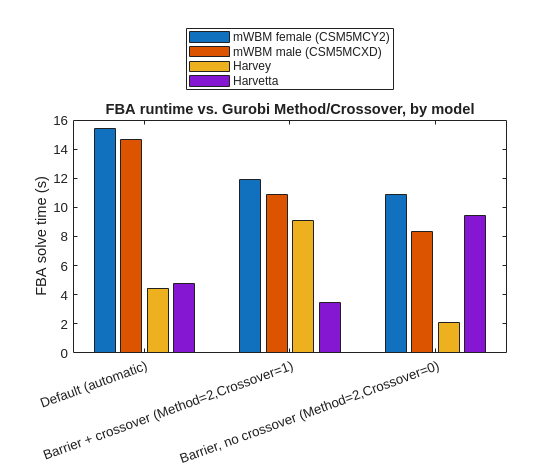

figure
bar(bigTime')
xticks(1:nConfigs)
xticklabels({configs.name})
xtickangle(20)
ylabel('FBA solve time (s)')
set(gca, 'TickLabelInterpreter', 'none')
legend({modelSet.name}, 'Location', 'northoutside', 'Interpreter', 'none')
title('FBA runtime vs. Gurobi Method/Crossover, by model')

Quantify the crossover cost directly for each model:

defaultIdx = strcmp({configs.name}, 'Default (automatic)');
crossIdx   = strcmp({configs.name}, 'Barrier + crossover (Method=2,Crossover=1)');
noCrossIdx = strcmp({configs.name}, 'Barrier, no crossover (Method=2,Crossover=0)');

crossoverSpeedup = table({modelSet.name}', bigTime(:, defaultIdx), bigTime(:, crossIdx), bigTime(:, noCrossIdx), ...
    100 * (bigTime(:, defaultIdx) - bigTime(:, noCrossIdx)) ./ bigTime(:, defaultIdx), ...
    'VariableNames', {'model', 'default_s', 'barrierCrossover_s', 'barrierNoCrossover_s', 'speedupVsDefault_pct'})

crossoverSpeedup = 4×5 table
              model               default_s    barrierCrossover_s    barrierNoCrossover_s    speedupVsDefault_pct
    __________________________    _________    __________________    ____________________    ____________________

    {'mWBM female (CSM5MCY2)'}     15.409            11.882                 10.893                  29.309       
    {'mWBM male (CSM5MCXD)'  }     14.636            10.858                 8.3292                  43.092       
    {'Harvey'                }     4.4463            9.0774                 2.0613                  53.641       
    {'Harvetta'              }     4.7597            3.4423                 9.4481                 -98.504       


## 4) FBA runtime benchmark: warm-starting a related re-solve

*Expected runtime: ~1-2 min - most of it the four initial crossover solves needed to produce a basis to warm-start from; the cold/warm re-solves themselves are the fastest thing measured in this whole tutorial.*

The scenario: you already solved a model, and now want to solve it again after a small, realistic change - here, halving the lower bound (uptake) of a single diet-exchange reaction that is present with the same bound in all four models, a stand-in for "try a different diet". Compare a cold re-solve against one seeded with the **first** solve's basis:

perturbRxn = 'Diet_EX_3mop[d]'; % present in all four models, lb = -0.1 as distributed

coldTime = nan(nModels, 1);
warmTime = nan(nModels, 1);
coldObj  = nan(nModels, 1);
warmObj  = nan(nModels, 1);

for mi = 1:nModels
    model = modelSet(mi).model;

    % Initial solve - must use crossover, so the returned basis is usable (Section 2)
    pInit = struct('Method', 2, 'Crossover', 1, 'printLevel', 0, 'timelimit', 300);
    solInit = optimizeCbModel(model, 'max', 0, true, pInit);

    % A small, realistic perturbation: halve one diet uptake bound
    origLb = model.lb(strcmp(model.rxns, perturbRxn));
    modelPerturbed = changeRxnBounds(model, perturbRxn, origLb * 0.5, 'l');

    pReSolve = struct('printLevel', 0, 'timelimit', 300);

    % Cold re-solve: no basis provided
    tic
    solCold = optimizeCbModel(modelPerturbed, 'max', 0, true, pReSolve);
    coldTime(mi) = toc;
    coldObj(mi)  = solCold.f;

    % Warm re-solve: seeded with the initial solve's basis
    modelWarm = modelPerturbed;
    modelWarm.basis = solInit.basis;
    tic
    solWarm = optimizeCbModel(modelWarm, 'max', 0, true, pReSolve);
    warmTime(mi) = toc;
    warmObj(mi)  = solWarm.f;

    fprintf('%-24s cold=%7.2fs  warm=%7.2fs  (%.1fx faster)\n', ...
        modelSet(mi).name, coldTime(mi), warmTime(mi), coldTime(mi) / warmTime(mi));
end

mWBM female (CSM5MCY2)   cold=  16.08s  warm=   0.50s  (31.9x faster)
mWBM male (CSM5MCXD)     cold=  14.94s  warm=   0.56s  (26.8x faster)
Harvey                   cold=   4.38s  warm=   0.14s  (32.0x faster)
Harvetta                 cold=   4.12s  warm=   0.15s  (27.6x faster)


Collect the results and plot them side by side:

warmStartResults = table({modelSet.name}', coldTime, warmTime, coldTime ./ warmTime, coldObj, warmObj, ...
    'VariableNames', {'model', 'cold_s', 'warm_s', 'speedupFactor', 'coldObjective', 'warmObjective'})

warmStartResults = 4×6 table
              model               cold_s    warm_s     speedupFactor    coldObjective    warmObjective
    __________________________    ______    _______    _____________    _____________    _____________

    {'mWBM female (CSM5MCY2)'}    16.085    0.50453       31.881              1                1      
    {'mWBM male (CSM5MCXD)'  }    14.935    0.55801       26.765              1                1      
    {'Harvey'                }    4.3793    0.13683       32.006              1                1      
    {'Harvetta'              }    4.1166    0.14927       27.579              1                1      


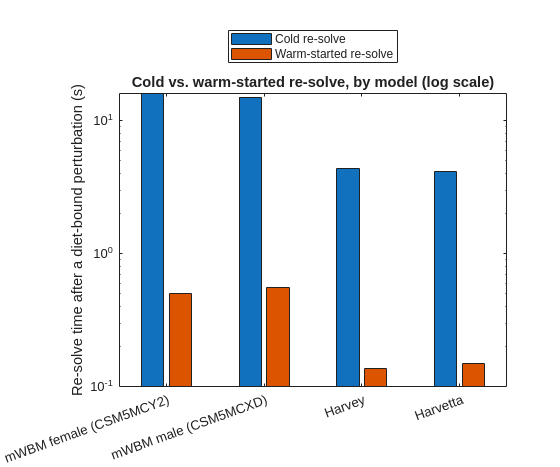


figure
bar([coldTime, warmTime])
xticks(1:nModels)
xticklabels({modelSet.name})
xtickangle(20)
ylabel('Re-solve time after a diet-bound perturbation (s)')
set(gca, 'YScale', 'log', 'TickLabelInterpreter', 'none')
legend({'Cold re-solve', 'Warm-started re-solve'}, 'Location', 'northoutside')
title('Cold vs. warm-started re-solve, by model (log scale)')

## 5) Interpreting the results

*Expected runtime: instant (discussion only, no further computation).*

**ANTICIPATED RESULTS**

- **Section 3 - crossover:** expect `'Barrier, no crossover'` to be fastest on **most**, not necessarily all, of the four models - in our own run it won on three of four by a healthy margin, but lost outright on one, where it was the **slowest** of the three configurations rather than the fastest. Each configuration here is solved only once (no replicates - see Section 3's intro), so some of this is plausibly single-shot noise on a large, degenerate LP rather than a stable property of that particular model; either way, do not treat "no-crossover wins" as guaranteed for every model you try it on - check `crossoverResults` for your own case rather than assuming.

- **Section 4 - warm-starting:** expect the warm-started re-solve to beat the cold re-solve by well over an order of magnitude on **every** model, with `coldObjective` and `warmObjective` matching to confirm both found the same answer. Unlike the crossover result above, this one was completely consistent across all four models in our run - the largest, and the most reliable, effect measured anywhere in this tutorial. A warm-started simplex re-solve of a **lightly perturbed** problem can converge in a handful of pivots, where a cold solve has to rebuild a solution from scratch across the model's entire constraint system.

These two levers solve different problems and actively work against one another if combined carelessly: skipping crossover denies you the basis that warm-starting depends on. Use `Crossover = 0` for a one-off solve where only the objective value matters (Section 3); use crossover **plus** warm-starting for a sequence of related solves, such as scanning several diets, personalising a cohort of individual WBMs, or repeated re-optimisation inside an iterative algorithm.

## TROUBLESHOOTING

**Problem:** `optimizeCbModel` on a raw (non-personalised) Harvey/Harvetta file returns an objective of 0 or fails immediately.

**Reason:** the raw files do not have `model.osenseStr` or `model.c` configured for whole-body FBA out of the box.

**Solution:** set `model.osenseStr = 'max'` and set the objective to the whole-body objective reaction with `changeObjective`, as in Section 1B - this only chooses which reaction is optimised, it does not touch any flux bound. The mWBMs in Section 1A do not need this - they are already configured.

**Problem:** every row in `crossoverResults`/|crossoverSpeedup| shows `objective = 1`, no matter which model or configuration produced it.

**Reason:** this is expected, not a bug - see the CRITICAL STEP in Section 1B. All four models ship with their whole-body objective reaction fixed at `lb = ub = 1`, so there is only ever one feasible objective value to find. The benchmark is measuring solve **time** for a fixed-rate feasibility problem across a huge constraint system, not variation in the objective itself.

**Solution:** nothing to fix - just do not expect the `objective` column to distinguish configurations the way `time_s` does. If you need a genuine unconstrained maximisation instead, relax that reaction's bounds yourself (e.g. `changeRxnBounds(model, objRxn, 1000, 'u')`) - but be aware that Gurobi's own numerical behaviour on these models can change once you do, since you are no longer testing the model as distributed, and not every solver handles a very large or infinite bound as cleanly as Gurobi does.

**Problem:** a solve reports `stat = 1` (success) but `origStat` contains the text `'OPTIMAL WARNING Primal optimality condition ... not satisfied'` rather than a plain `'OPTIMAL'`.

**Reason:** this is the same tolerance trade-off measured in Section 2 - the interior-point solution from `Crossover = 0` does not, by itself, satisfy `solveCobraLP`'s internal feasibility check as tightly as a crossed-over (vertex) solution would. `optimizeCbModel` still reports the solve as usable (`stat = 1`), but the warning is worth reading, not ignoring.

**Solution:** if the small residual matters for your downstream use of the flux vector (rather than just the objective value), re-solve with `Crossover = 1`.

**Problem:** setting `model.basis` makes no difference to solve time, or the solve is slower than a plain cold solve.

**Reason:** a basis only helps when it comes from a solve that actually produced one (`Crossover = 1`, not `0` - Section 2) and when the new problem is genuinely **related** to the one the basis came from. A basis from an unrelated model, or from a model with a different number of reactions/constraints, will not help and can error outright.

**Solution:** generate the basis with `Crossover = 1` on the **same** model you are about to perturb, as in Section 4, and only reuse it for small, incremental changes (a handful of bound changes, not a structurally different problem).

## TIMING

On the machine used to prepare this tutorial (12 logical cores, Gurobi 11.0.3), the whole tutorial - setup, model loading, Sections 2-5 - took about **6.5 minutes** end to end. Section 3 (twelve solves) took roughly 2 minutes; Section 4 took roughly 1.5 minutes, almost all of it the four initial crossover solves needed to produce a basis to warm-start from - the cold/warm re-solves themselves, once that basis existed, took well under a second each and were consistently the fastest thing measured anywhere in this tutorial. Absolute numbers will differ on your hardware, Gurobi version and the exact models you load - re-run Sections 3-4 on your own machine before trusting any specific number in this tutorial.

## ACKNOWLEDGMENTS

The `fastBarrier` option for `fluxVariability` and the underlying benchmarking used to design it, referenced in the INTRODUCTION, were developed as part of ongoing COBRA Toolbox solver-performance work.

## REFERENCES

[1] Thiele, I., et al. Personalized whole-body models integrate metabolism, physiology, and the gut microbiome. *Mol. Syst. Biol.* 16, e8982 (2020).

[2] Heinken, A., & Thiele, I. (2022). Microbiome Modelling Toolbox 2.0: tractable modelling of microbiome communities. *Bioinformatics*, 38(8), 2367-2368.

[3] Gurobi Optimization, LLC. Gurobi Optimizer Reference Manual, Parameters: `Method`, `Crossover`. [<https://www.gurobi.com/documentation/current/refman/parameter_descriptions.html](https://www.gurobi.com/documentation/current/refman/parameter_descriptions.html)> (2024).

[4] Orth, J.D., Thiele, I., Palsson, B.O. What is flux balance analysis? *Nat. Biotechnol.* 28, 245-248 (2010).

[5] Heirendt, L., Arreckx, S., Pfau, T., et al. Creation and analysis of biochemical constraint-based models using the COBRA Toolbox v.3.0. *Nat. Protoc.* 14, 639-702 (2019).